# Перебор параметров при помощи `parfor`

В этом примере показано, как выполнить перебор параметров с использованием цикла parfor. Результаты каждой симуляции будут выводится по мере ее завершения

Используется классическая система, осциллятор Ван-дер-Поля. Эта система может быть выражена как набор ОДУ, зависящих от двух параметров, $\mu$ and $\nu$: 


$$\dot{x } =\nu y$$



$$\dot{y } =\mu \left(1-x^2 \right)y -x$$


## Создание входных данных

gridSize = 12;
nu = linspace(100, 150, gridSize);
mu = linspace(0.5, 2, gridSize);

## Создание графика поверхности

[N,M] = meshgrid(nu,mu);
Z = nan(size(N));
c = surf(N, M, Z);
xlabel('Значения \mu','Interpreter','Tex')
ylabel('Значения \nu','Interpreter','Tex')
zlabel('Средний период  y')
view(137, 30)
axis([100 150 0.5 2 0 500]);
set(gcf,'Visible','off')

## Обновление поверхности после каждого расчета

D = parallel.pool.DataQueue;
D.afterEach(@(x) updateSurface(c, x));

## Запуск перебора параметров

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Analyzing and transferring files to the workers ...done.


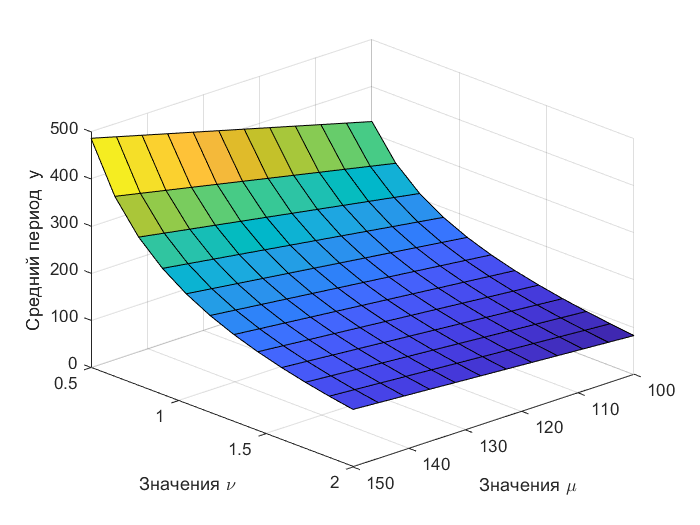

parfor ii = 1:numel(N)
    [t, y] = solveVdp(N(ii), M(ii));
    l = islocalmax(y(:, 2));
    send(D, [ii mean(diff(t(l)))]);
end

## Вспомогательные функции

function [t, y] = solveVdp(mu, nu)
f = @(~,y) [nu*y(2); mu*(1-y(1)^2)*y(2)-y(1)];
[t,y] = ode23s(f,[0 20*mu],[2; 0]);
end

function updateSurface(s, d)
s.ZData(d(1)) = d(2);
drawnow('limitrate');
end